# Descrete Fourier Transform

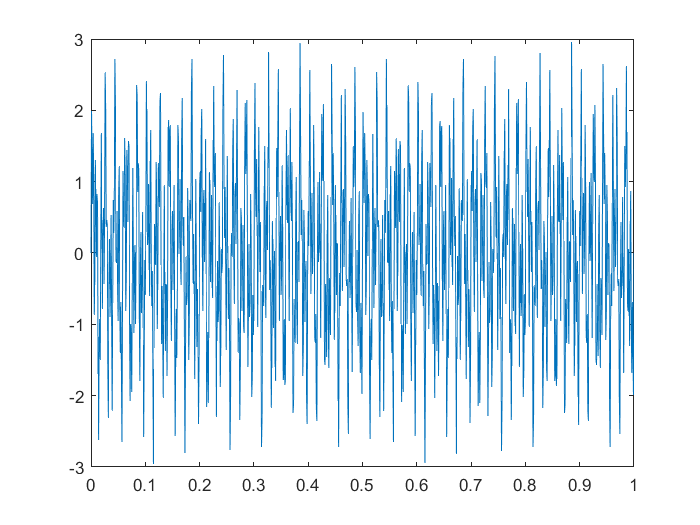

dx = 0.001;
x = 0:dx:1;

fx = sin(2*pi*50*x) + sin(2*pi*120*x) + sin(2*pi*276*x);

figure(1);
plot(x,fx);

## Find Frequencies

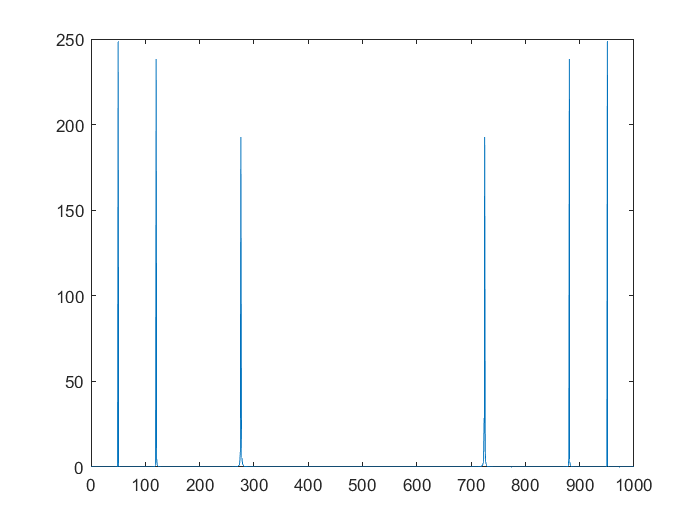

N = length(x);
Wn = exp(-2*pi*1i/N);

% DFT matrix using loop (slow)
% DFT = zeros(N);
% for i=1:N
%     for j=1:N
%         DFT(i,j) = Wn^((i-1)*(j-1));
%     end
% end

% DFT using meshgrid (fast)
[I,J] = meshgrid(1:N,1:N);
DFT = Wn.^(I-1).^(J-1);

fw = DFT*fx';

PSD = fw.*conj(fw)/N; % Power spectrum density (how much power is in each spectrum), this is just the inner product of fw iwth itself

figure(2);
plot((1:N)-1,PSD);